# **Stress Simulation**

clear;
clc;


wall = getMaterialProperties("al6061");


wallThickness = 0.08*2.54/100; % m   Wall thickness
innerDiameter = 2.33*2.54/100; % m   Inner diameter
outerPressure = 45*10^5; %     Pa  Outer wall pressure
innerPressure = 5.4*10^5; %     Pa  Inner wall pressure
outerTemp     = 496-273.15; %   C   Outer wall temperature
innerTemp     = 527-273.15; %   C   Inner wall temperature

ambientPressure = 1*10^5; %  Pa
ambientTemperature = 25; %   C

outerDiameter = innerDiameter + 2*wallThickness;

steadyCond.OD = outerDiameter;
steadyCond.ID = innerDiameter;
steadyCond.P_o = outerPressure;
steadyCond.P_i = innerPressure;
steadyCond.E = wall.getYoungsModulus((outerTemp + innerTemp)/2);
steadyCond.alpha = wall.a;
steadyCond.T_o = outerTemp;
steadyCond.T_i = innerTemp;
steadyCond.v = wall.v;
maxStress = getMaxStress(steadyCond);

Using thin walled assumption (29.125000 > 20).


startupCond.OD = outerDiameter;
startupCond.ID = innerDiameter;
startupCond.P_o = 4*outerPressure;
startupCond.P_i = ambientPressure;
startupCond.E = wall.getYoungsModulus(ambientTemperature);
startupCond.alpha = wall.a;
startupCond.T_o = ambientTemperature;
startupCond.T_i = ambientTemperature;
startupCond.v = wall.v;
startupStress = getMaxStress(startupCond);

Using thin walled assumption (29.125000 > 20).


yield = wall.getYieldStrength(innerTemp);
yield_startup = wall.getYieldStrength(ambientTemperature);

FOS = abs(yield/maxStress.totalStress);
FOS_startup = abs(yield_startup/startupStress.totalStress);

TE.L = innerDiameter;
TE.a = wall.a;
TE.deltaT = (outerTemp + innerTemp)/2 - 25;
thermalExpansion = getThermalExpansion(TE); % Correct this to add stress?

fprintf('Steady State Factor of Safety: %.2f', FOS);

Steady State Factor of Safety: 0.46

fprintf('Startup Factor of Safety: %.2f', FOS_startup);

Startup Factor of Safety: 1.06



fprintf('Combined thermal expansion (in): %.4f', thermalExpansion*100/2.54);

Combined thermal expansion (in): 0.0125

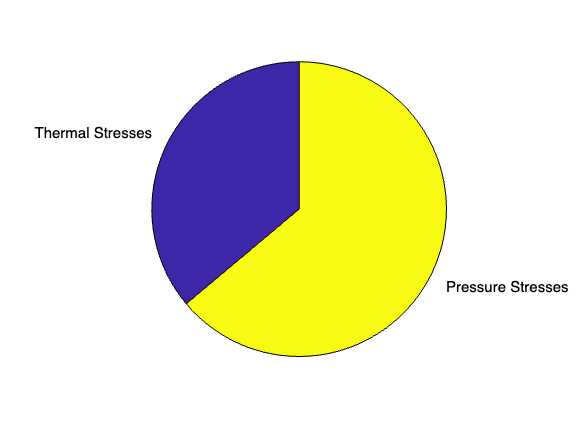


pie(abs([maxStress.thermalStress,maxStress.pressureStress]), ...
    [0,0],["Thermal Stresses", "Pressure Stresses"])